## Example #1

### Random tetrahedron from the 3D space

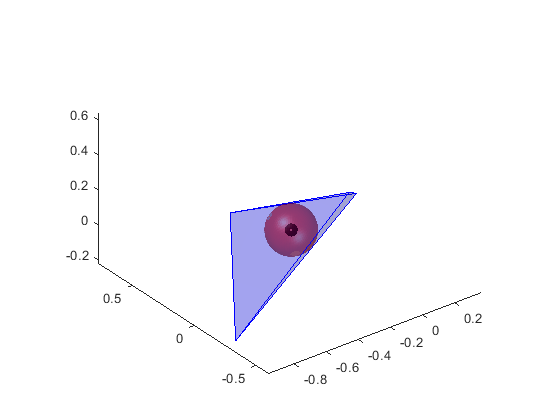

V = 2*(rand(3,4)-0.5);
tetrahedron_insphere(V(:,1),V(:,2),V(:,3),V(:,4));

## Example #2

### Regular tetrahedron in the unit ball

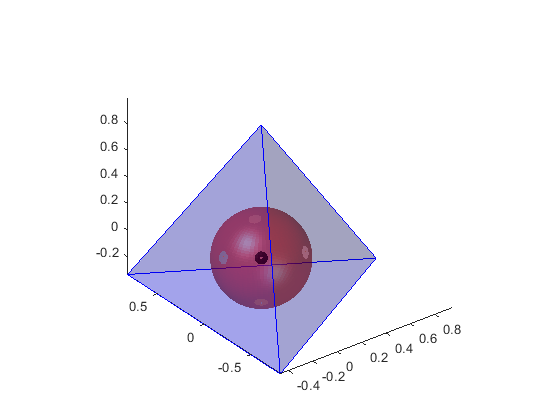

V1 = [0 0 1]';
V2 = [2*sqrt(2)/3 0 -1/3]';
V3 = [-sqrt(2)/3 sqrt(6)/3 -1/3]';
V4 = [-sqrt(2)/3 -sqrt(6)/3 -1/3]';
[I,radius,rc] = tetrahedron_insphere(V1,V2,V3,V4,true);

rc % expected : rc = 1

rc = logical
   1

## Example #3

### Flat / degenerated tetrahedron

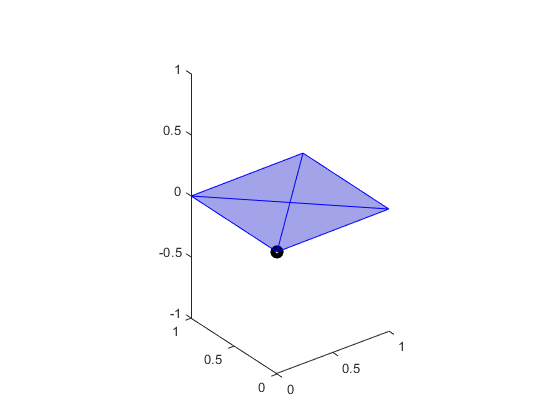

V1 = [0 0 0]';
V2 = [1 0 0]';
V3 = [0 1 0]';
V4 = [1 1 0]';
[I,radius,rc] = tetrahedron_insphere(V1,V2,V3,V4,true);

rc % expected : rc = 0

rc = logical
   0